clear;
clear all;
clc;

## Entrega 3 - PMR3523 Controle Moderno

CÃ¡lculo de Polos e Zeros Ã‚ngelo Bianco Yanagita - 6649978 DiÃ´go Cavalcante Rodrigues Lopes - 11180872

As equaÃ§Ãµes utilizadas sÃ£o:

Sendo as variÃ¡veis:


$$\begin{array}{l}x={\left\lbrack \begin{array}{cccccc}x_g  & y_g  & \psi 
\; & u & v & r\end{array}\right\rbrack }^T \\u={\left\lbrack \begin{array}{ccc}F_x  
& F_y  & F_z \end{array}\right\rbrack }^T \\y={\left\lbrack \begin{array}{ccc}x_g  
& y_g  & \psi \;\end{array}\right\rbrack }^T \end{array}$$


Considerando os parÃ¢metros do navio de suporte Ã plataforma Maersk Handler: 

m = 7240e3;
izz = 2750e6;
m11 = 640e3;
m22 = 6400e3;
m66 = 1560e6;
m26 = 7900e3;

LinearizaÃ§Ã£o de acordo com as seguintes condiÃ§Ãµes:

e entradas nos esforÃ§os propulsores todas nulas.

syms xg psi u v r Fx Fy Fz v_dot_lin r_dot_lin

xg_dot = u*cos(psi) - v*sin(psi)

$$xg\_dot = u\,\cos\left(\psi \right)-v\,\sin\left(\psi \right)$$

yg_dot = u*sin(psi) + v*cos(psi)

$$yg\_dot = v\,\cos\left(\psi \right)+u\,\sin\left(\psi \right)$$

psi_dot = r

$$psi\_dot = r$$

u_dot = (Fx + (m*xg + m26)*r^2 + (m + m22)*v*r)/(m+m11)

$$u\_dot = \frac{\mathrm{Fx}}{7880000}+\frac{341\,r\,v}{197}+\frac{r^{2}\,\left(7240000\,\mathrm{xg}+7900000\right)}{7880000}$$

v_dot = (Fy -(m*xg + m26)*r_dot_lin - (m + m11)*u*r)/(m+m22)

$$v\_dot = \frac{\mathrm{Fy}}{13640000}-\frac{r_{\mathrm{dot},\mathrm{lin}}\,\left(7240000\,\mathrm{xg}+7900000\right)}{13640000}-\frac{197\,r\,u}{341}$$

r_dot = (Fz - (m*xg + m26)*(v_dot_lin + u*r) - (m22 - m11)*u*v)/(izz + m66)

$$r\_dot = \frac{\mathrm{Fz}}{4310000000}-\frac{72\,u\,v}{53875}-\frac{\left(v_{\mathrm{dot},\mathrm{lin}}+r\,u\right)\,\left(7240000\,\mathrm{xg}+7900000\right)}{4310000000}$$

Linearizando as equaÃ§Ãµes:

lin_xg_dot = taylor(xg_dot, [u, v, psi], 0 , 'Order', 2)

$$lin\_xg\_dot = u$$


lin_yg_dot = taylor(yg_dot, [u, v, psi], 0 , 'Order', 2)

$$lin\_yg\_dot = v$$


lin_psi_dot = taylor(psi_dot, r , 0 , 'Order', 2)

$$lin\_psi\_dot = r$$


lin_u_dot = taylor(u_dot, [xg, r, v, Fx], 0 , 'Order', 2)

$$lin\_u\_dot = \frac{\mathrm{Fx}}{7880000}$$


lin_v_dot = taylor(v_dot, [xg, r_dot_lin, u, r, Fy], 0 , 'Order', 2)

$$lin\_v\_dot = \frac{\mathrm{Fy}}{13640000}-\frac{395\,r_{\mathrm{dot},\mathrm{lin}}}{682}$$


lin_r_dot = taylor(r_dot, [xg, v_dot_lin, u, r, v, Fz], 0 , 'Order', 2)

$$lin\_r\_dot = \frac{\mathrm{Fz}}{4310000000}-\frac{79\,v_{\mathrm{dot},\mathrm{lin}}}{43100}$$

Substituindo o termo $\dot{\;r_{\textrm{lin}} }$ no termo $\dot{\;v_{\textrm{lin}}  }$, tem-se:


$$\dot{\;v_{\textrm{lin}} } =\frac{\;F_y }{13640000}-\frac{395}{682}\left(\frac{\;F_z 
}{4310000000}-\frac{79}{43100}\dot{\;v_{\textrm{lin}} } \right)$$


a= 395/682;
b = 79/43100;
c = a*b

c = 0.0011

d = a/4310000000

d = 1.3438e-10


$$\dot{\;v_{\textrm{lin}} } -0,0011\dot{\;v_{\textrm{lin}} } =\frac{\;F_y 
}{13640000}-d*F_z$$


e = 1/(13640000*0.9989)

e = 7.3395e-08

f = d/0.9989

f = 1.3453e-10


$$\dot{\;v_{\textrm{lin}} } =e*F_y -f*F_z$$


Fazendo a substituiÃ§Ã£o do termo $\dot{\;v_{\textrm{lin}} }$ no termo $\dot{\;r_{\textrm{lin}}  }$ tem-se:


$$\dot{\;r_{\textrm{lin}} } =\frac{F_z }{4310000000}-\frac{\;79}{43100}\left(e*F_y 
-f*F_z \right)$$


g = (79/43100)*e

g = 1.3453e-10

h = (79/43100)*f

h = 2.4658e-13

i = (1/4310000000)+h

i = 2.3227e-10


$$\dot{\;r_{\textrm{lin}} } =-g*F_y \;+\;i*F_z$$


Colocando os termos na forma matricial do espaÃ§o de estados:


$$\begin{array}{l}\delta \dot{x} =A\delta x\left(t\right)+B\delta u\left(t\right)\\\;\delta 
y=C\delta x\left(t\right)+D\delta u\left(t\right)\;\end{array}$$



$$A=\left\lbrack \begin{array}{cccccc}0 & 0 & 0 & 1 & 0 & 0\\0 & 0 & 0 & 0 
& 1 & 0\\0 & 0 & 0 & 0 & 0 & 1\\0 & 0 & 0 & 0 & 0 & 0\\0 & 0 & 0 & 0 & 0 & 0\\0 
& 0 & 0 & 0 & 0 & 0\end{array}\right\rbrack$$ $$B=\left\lbrack \begin{array}{ccc}0 
& 0 & 0\\0 & 0 & 0\\0 & 0 & 0\\1,269*{10}^{-7}  & 0 & 0\\0 & e & -f\\0 & -g 
& i\end{array}\right\rbrack$$ $$C=\left\lbrack \begin{array}{cccccc}1 & 0 & 
0 & 0 & 0 & 0\\0 & 1 & 0 & 0 & 0 & 0\\0 & 0 & 1 & 0 & 0 & 0\end{array}\right\rbrack$$ 
$$D=\left\lbrack \begin{array}{c}0\end{array}\right\rbrack$$


Definindo as caracterÃ­sticas do modelo:

A = [0 0 0 1 0 0
     0 0 0 0 1 0
     0 0 0 0 0 1
     0 0 0 0 0 0
     0 0 0 0 0 0
     0 0 0 0 0 0];
 
B = [0 0 0 
    0 0 0
    0 0 0
    1.269e-07 0 0
    0 e -f
    0 -g i];

C = [1 0 0 0 0 0
    0 1 0 0 0 0 
    0 0 1 0 0 0];

D = zeros(3,3);

## Polos e zero do sistema:

polos_do_sistema = eig(A)

polos_do_sistema =      0
     0
     0
     0
     0
     0


% A) Polos do sistema: ${\left\lbrack 0\;0\;0\;0\;0\;0\right\rbrack }^T$
% 
% B) Matriz de TransferÃªncia $G\left(S\right)$:

%Matriz adjunta
syms s

sI = [s 0 0 0 0 0
    0 s 0 0 0 0 
    0 0 s 0 0 0
    0 0 0 s 0 0
    0 0 0 0 s 0
    0 0 0 0 0 s]

$$sI = \left(\begin{array}{cccccc} s & 0 & 0 & 0 & 0 & 0\\ 0 & s & 0 & 0 & 0 & 0\\ 0 & 0 & s & 0 & 0 & 0\\ 0 & 0 & 0 & s & 0 & 0\\ 0 & 0 & 0 & 0 & s & 0\\ 0 & 0 & 0 & 0 & 0 & s \end{array}\right)$$


sI_A = sI-A

$$sI\_A = \left(\begin{array}{cccccc} s & 0 & 0 & -1 & 0 & 0\\ 0 & s & 0 & 0 & -1 & 0\\ 0 & 0 & s & 0 & 0 & -1\\ 0 & 0 & 0 & s & 0 & 0\\ 0 & 0 & 0 & 0 & s & 0\\ 0 & 0 & 0 & 0 & 0 & s \end{array}\right)$$

adjunta = adjoint(sI_A)

$$adjunta = \left(\begin{array}{cccccc} s^{5} & 0 & 0 & s^{4} & 0 & 0\\ 0 & s^{5} & 0 & 0 & s^{4} & 0\\ 0 & 0 & s^{5} & 0 & 0 & s^{4}\\ 0 & 0 & 0 & s^{5} & 0 & 0\\ 0 & 0 & 0 & 0 & s^{5} & 0\\ 0 & 0 & 0 & 0 & 0 & s^{5} \end{array}\right)$$


%Determinante

determinante = det(sI_A)

$$determinante = s^{6}$$


%Zeros da MF
numerador = C*adjunta*B

$$numerador = \left(\begin{array}{ccc} \frac{299634153338079\,s^{4}}{2361183241434822606848} & 0 & 0\\ 0 & \frac{5545532910682273\,s^{4}}{75557863725914323419136} & -\frac{5204308936688551\,s^{4}}{38685626227668133590597632}\\ 0 & -\frac{5204308936688551\,s^{4}}{38685626227668133590597632} & \frac{8985322568043613\,s^{4}}{38685626227668133590597632} \end{array}\right)$$

zeros_MF = det(C*adjunta*B)

$$zeros\_MF = \frac{7636193476893582392694396861633887877652732089873\,s^{12}}{3533694129556768659166595001485837031654967793751237916243212402585239552}$$


G = (C*adjunta*B)/determinante;

G_numeric = vpa((C*adjunta*B)/determinante)

$$G\_numeric = \left(\begin{array}{ccc} \frac{0.00000012690000000000000473956811297693}{s^{2}} & 0 & 0\\ 0 & \frac{0.000000073394516959858193427337100332025}{s^{2}} & -\frac{0.00000000013452823294266349187945545830026}{s^{2}}\\ 0 & -\frac{0.00000000013452823294266349187945545830026}{s^{2}} & \frac{0.00000000023226514455690185911893469421224}{s^{2}} \end{array}\right)$$

% C) PÃ³los da Matriz de TransferÃªncia
% 
% 
% Como o determinante da Matriz de TransferÃªncia (MF) Ã© $s^6$, *os polos da 
% MF sÃ£o:* ${\left\lbrack 0\;0\;0\;0\;0\;0\right\rbrack }^T$
% 
% 
% D) Zero de transmissÃ£o
% Verificando os zeros de transmissÃ£o:

zero_de_transmissao = tzero(A,B,C,D)

zero_de_transmissao = 0x1 double

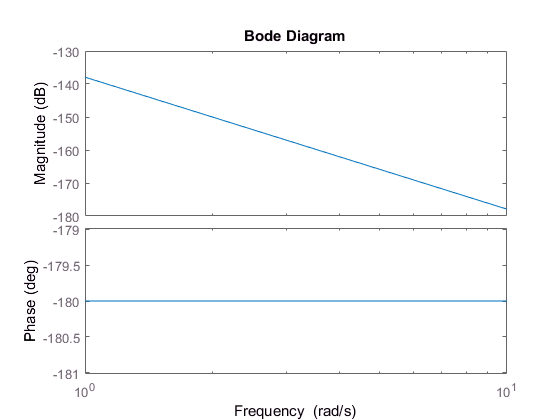

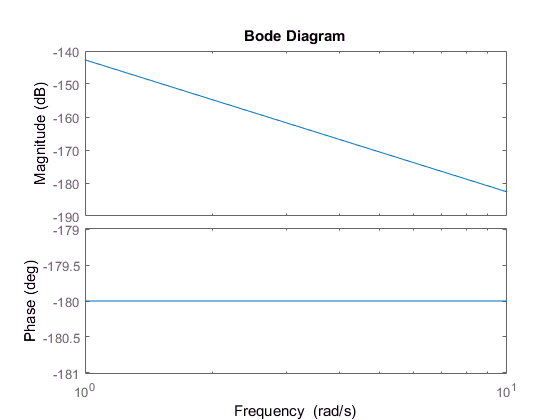

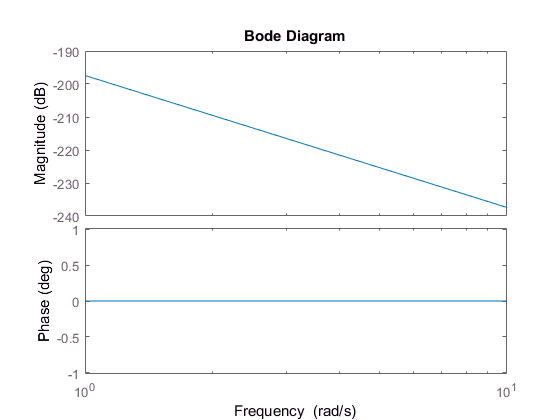

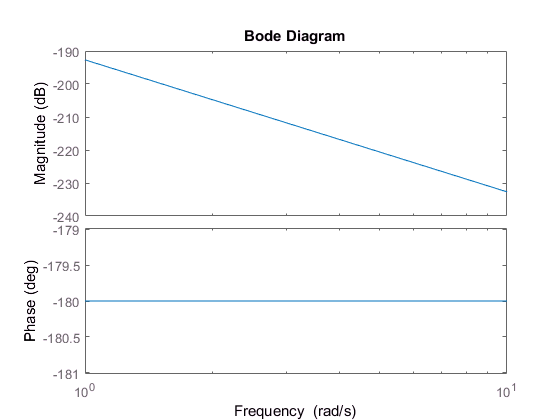

syms s 

x=[1 2 2 3 3];
y=[1 2 3 2 3];

for c=1:5
    
    [nf, df] = numden(G_numeric(y(c),x(c)));
    
    tfn = sym2poly(nf);
    tfd = sym2poly(df);
    
    H = tf(tfn, tfd);
    
    figure(c);
    bode(H)
    
end